YMMH5=loadrobot("yaskawaMotomanMH5","DataFormat","row","Gravity",[0 0 9.81])

YMMH5 =   rigidBodyTree with properties:

     NumBodies: 6
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'link_s'  'link_l'  'link_u'  'link_r'  'link_b'  'link_t'}
      BaseName: 'base_link'
       Gravity: [0 0 9.8100]
    DataFormat: 'row'


showdetails(YMMH5)

--------------------
Robot: (6 bodies)

 Idx     Body Name     Joint Name     Joint Type     Parent Name(Idx)   Children Name(s)
 ---     ---------     ----------     ----------     ----------------   ----------------
   1        link_s        joint_s       revolute         base_link(0)   link_l(2)  
   2        link_l        joint_l       revolute            link_s(1)   link_u(3)  
   3        link_u        joint_u       revolute            link_l(2)   link_r(4)  
   4        link_r        joint_r       revolute            link_u(3)   link_b(5)  
   5        link_b        joint_b       revolute            link_r(4)   link_t(6)  
   6        link_t        joint_t       revolute            link_b(5)   
--------------------


DK=getTransform(YMMH5,[45,15,20,25,30,12],'link_s','link_t')

DK =    -0.8954    0.1308   -0.4257    0.1558
    0.3362    0.8255   -0.4534   -0.3142
    0.2921   -0.5491   -0.7831   -0.4230
         0         0         0    1.0000


ropiya=tform2eul(DK)

ropiya =     2.7824   -0.2964   -2.5301


Roll=ropiya(1)

Roll = 2.7824

Pitch=ropiya(2)

Pitch = -0.2964

Yaw=ropiya(3)

Yaw = -2.5301

X=326.41/1000;
Y=352.26/1000;
Z=412.18/1000;
P=[X;Y;Z]

P =     0.3264
    0.3523
    0.4122


T=rt2tr(rotx(Yaw,'deg')*roty(Pitch,'deg')*rotz(Roll,'deg'),P)

T =     0.9988   -0.0485   -0.0052    0.3264
    0.0487    0.9978    0.0441    0.3523
    0.0030   -0.0443    0.9990    0.4122
         0         0         0    1.0000



ik = inverseKinematics('RigidBodyTree',YMMH5);
weights = [0.25 0.25 0.25 1 1 1];
initialguess = YMMH5.homeConfiguration;
[configSoln,solnInfo] = ik('link_t',DK,weights,initialguess)

configSoln =    -1.0228    2.6180    1.2005   -2.4380    1.9484    2.6346


solnInfo = struct with fields:
           Iterations: 1500
    NumRandomRestarts: 53
        PoseErrorNorm: 0.2109
             ExitFlag: 2
               Status: 'best available'


configSolnd=rad2deg(configSoln)

configSolnd =   -58.6005  150.0004   68.7854 -139.6891  111.6338  150.9512


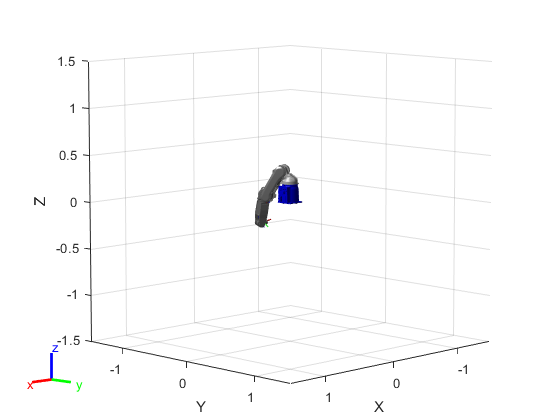

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


show(YMMH5,configSoln)



gik=generalizedInverseKinematics('RigidBodyTree',YMMH5,'ConstraintInputs',{'position','aiming'})

gik =   generalizedInverseKinematics with properties:

      NumConstraints: 2
    ConstraintInputs: {'position'  'aiming'}
       RigidBodyTree: [1×1 rigidBodyTree]
     SolverAlgorithm: 'BFGSGradientProjection'
    SolverParameters: [1×1 struct]


posTgt = constraintPositionTarget('link_t');
posTgt.TargetPosition = [-0.444 0 -0.6799];

aimCon = constraintAiming('link_t');
aimCon.TargetPoint = [0.0 0.0 0.0];


[configSoln2,solnInfo2] = gik(initialguess,posTgt,aimCon)

configSoln2 =     2.9671    2.6180    1.2274   -0.5366   -0.4498   -2.7406


solnInfo2 = struct with fields:
              Iterations: 1500
       NumRandomRestarts: 33
    ConstraintViolations: [1×2 struct]
                ExitFlag: 2
                  Status: 'best available'


configSolnd2=rad2deg(configSoln2)

configSolnd2 =   170.0023  150.0004   70.3266  -30.7440  -25.7691 -157.0250


%show(YMMH5,configSolnd2)